# Run Param_lab3_real.mlx

## Run General parameter

step_amplitude = 50;

# Simulate step 50 [deg] lqr robust (lab3_lqr_robust_box_sim.slx ) or real

## Salva dati 50 deg lqr robust tracking


t = ScopeData1.time;
tetha_h = ScopeData1.signals(1).values;  
tetha_d = ScopeData1.signals(2).values;
ref_signal = ScopeData1.signals(3).values;
command_u = ScopeData1.signals(4).values;
save("lqr_robust_lab3_50_real.mat",'t','tetha_h','tetha_d','ref_signal','command_u');



## Stampa grafico

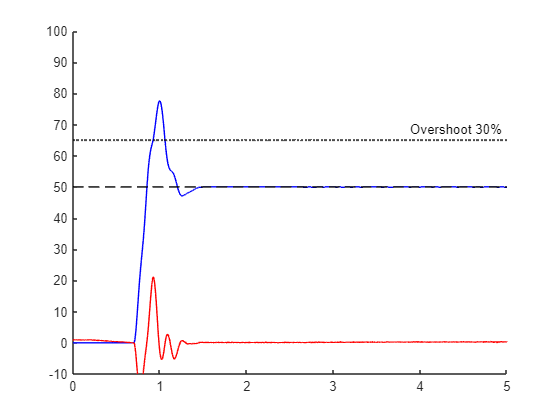

% grafico step 50 deg

load("lqr_robust_lab3_50_real.mat");
figure;
% plot(t,ref,'k--');
yline(65, 'k:','LineWidth', 1.5, 'Label', 'Overshoot 30%');
hold on 
plot(t,tetha_h,'b');
plot(t,tetha_d,'r');
plot(t,ref_signal,'k--');
axis([0 5 -10 100])
hold off

#### Step response parameters


step_50_wind_up_robust_lqr = stepinfo(tetha_h, t, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_robust_lqr);

         RiseTime: 0.1124
    TransientTime: 1.2829
     SettlingTime: 1.2829
      SettlingMin: 45.3600
      SettlingMax: 77.5800
        Overshoot: 55.1600
       Undershoot: 0
             Peak: 77.5800
         PeakTime: 0.9940

